# 基于DCT变换的图像水印方法

书本中提供的方法，我总是无法得到很好的效果。也许是我的小改出现了问题吧。

carrierI=imread('cameraman.tif');
watermarkI=imread('21.bmp');
watermarkI=imbinarize(watermarkI);

%定义DCT中频系数
DCT_coef=[
    0,0,0,1,1,1,1,0;
    0,0,1,1,1,1,0,0;
    0,1,1,1,1,0,0,0;
    1,1,1,1,0,0,0,0;
    1,1,1,0,0,0,0,0;
    1,1,0,0,0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0
];
%设置水印强度
k=20;

## 嵌入水印

%设置相同的随机数生成器状态J,作为检测时的系统密钥K
rand('state',7);
pn_sequence_zero = round(rand( 1, sum(DCT_coef(:)))); 
watermarkedI=DCT_encode(carrierI,watermarkI,DCT_coef,k,pn_sequence_zero);

%显示峰值信噪比
xsz =255 * 255 * numel(carrierI)/ sum( sum( ( carrierI - watermarkedI).^2));
psnr= 10 * log10( xsz);
fprintf("图像失真程度指标：峰值信噪比PSNR=%g",psnr);

图像失真程度指标：峰值信噪比PSNR=48.5722

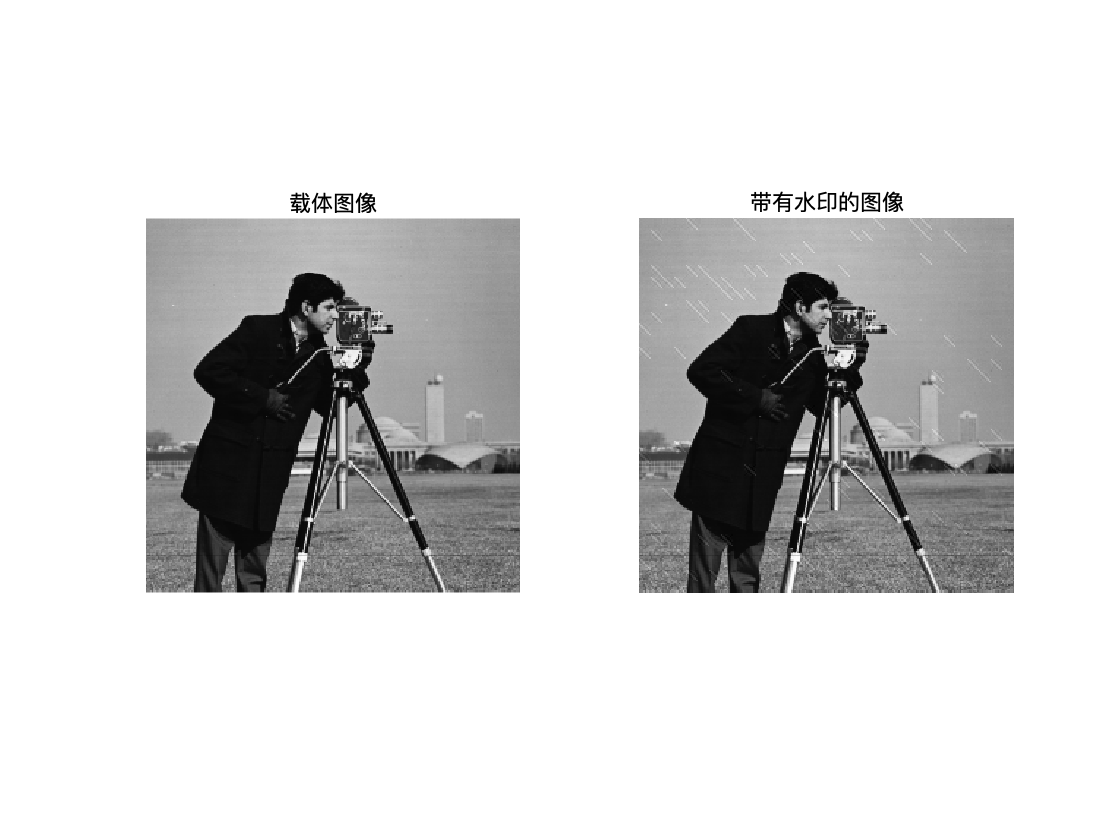

figure;
subplot(1,2,1);
imshow(carrierI);
title("载体图像");
subplot(1,2,2);
imshow(watermarkedI);
title("带有水印的图像")

## 提取水印

%设置相同的随机数生成器状态J,作为检测时的系统密钥K
rand('state',7);
pn_sequence_zero = round(rand( 1, sum(DCT_coef(:)))); 
watermark2I=DCT_decode(watermarkedI,carrierI,DCT_coef,pn_sequence_zero);
%计算提取的水印和原始水印的相似程度
sim = corr2( watermarkI,watermark2I );
fprintf("相似度%g",sim);

相似度-0.756504

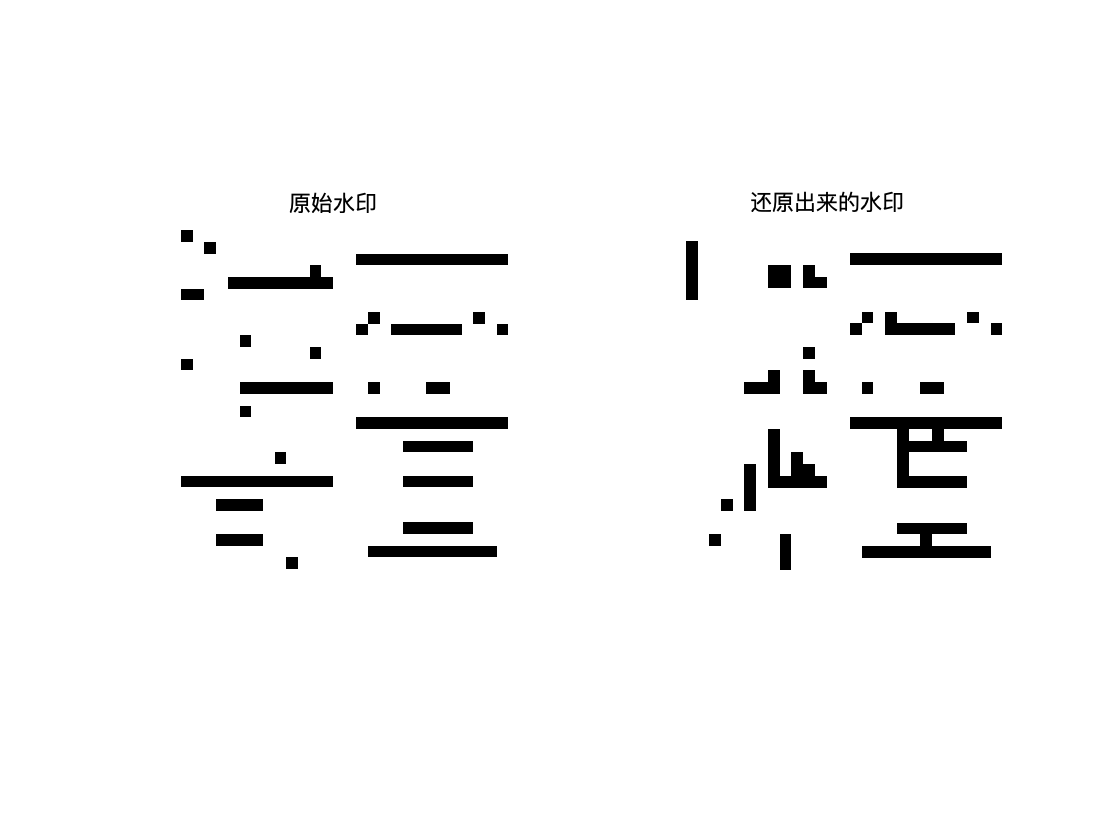

figure();
subplot(1,2,1);
imshow(watermarkI);
title('原始水印')
subplot(1,2,2)
imshow(watermark2I==0);
title('还原出来的水印')